Импорт данных:

spectra = importdata("spectra.csv"); 
starNames = importdata("star_names.csv"); 
lambdaStart = importdata("lambda_start.csv"); 
lambdaDelta = importdata("lambda_delta.csv"); 

Константы:

lambdaPr = 656.28; %ожидаемая скорость, нм 
speedOfLight = 299792.458; %скорость света, км/с 

Определение диапазона длин волн:

nObs = size(spectra,1); 
nStar = size(spectra, 2); 
lambdaEnd = lambdaStart + (nObs - 1) * lambdaDelta; 
lambda = (lambdaStart : lambdaDelta : lambdaEnd)'; 

Расчет скоростей:

[SHa, Idx] = min(spectra); 
lamdaHa = lambda(Idx)'; 
z = (lamdaHa / lambdaPr) - 1; 
speed = z' * speedOfLight ; 

Имена звезд, удаляющихся от Земли:

movaway = starNames(speed > 0); 

Построение графика:

fg1 = figure; 
i = 1; 
for i = 1 : nStar 
    hold on 
      if speed(i) > 0 
      plot(lambda, spectra(:, i), 'LineWidth', 3) %красное смещение 
      else 
      plot(lambda, spectra(:, i), "--", 'LineWidth', 1)%синие смещение 
      end 
    i = i + 1; 
end 
  set(gcf, 'visible', 'on') 
  xlabel('Длина волны, нм') 
  ylabel(['Интенсивность,зрг/см^2/', char(197)]) 
  title('Спектры звезд') 
  text(635, 3.25 * 10^(-13), 'Юрко Ксения, Б01-008') 
  grid on 
  legend(starNames) 
  hold off 

 Сохранение графика:

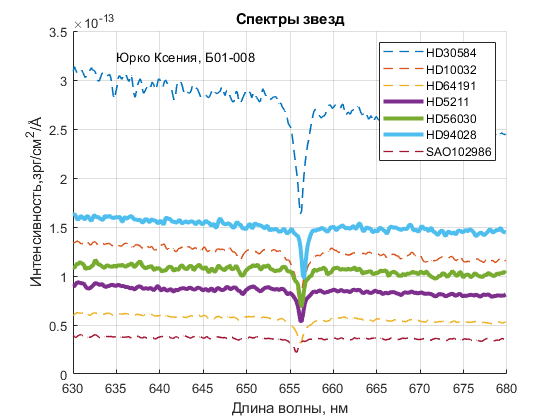

  saveas(fg1, 'StarsSpectra.png')